# **How to handle the data and make figures**

proj_dir = './data+codes_pcbi2025_aliobaibk';
if ~isfolder(proj_dir)
    error(['The "proj_dir" variable is not set to an existing directory.\n', ...
        'Ensure "proj_dir" points to the directory where the repository was ', ...
        'cloned.\nFor example, if you cloned the repository into ', ...
        '"./data+codes_pcbi2025_aliobaibk",\n', ...
        'use: proj_dir = ''./data+codes_pcbi2025_aliobaibk''.'], '')
end

addpath(genpath(fullfile(proj_dir, 'codes', 'util')))
addpath(genpath(fullfile(proj_dir, 'codes', 'functions')))

## Displaying the raw structural connectomes

- Loads and sets up data

in_file = fullfile(proj_dir, 'data', 'connectomes', 'raw', ...
    'HCP-average_laus18-3_sc.csv');
C_n = readmatrix(in_file);

in_file = fullfile(proj_dir, 'data', 'connectomes', 'raw', ...
    'HCP-average_laus18-3_legend.txt');
L_n = readcell(in_file, 'Delimiter', '');

in_file = fullfile(proj_dir, 'data', 'connectomes', 'raw', ...
    'ICBM152A09C_laus18-3_mid-fs-311558V_weights.csv');
C_a = readmatrix(in_file);

in_file = fullfile(proj_dir, 'data', 'connectomes', 'raw', ...
    'ICBM152A09C_laus18-3_mid-fs-311558V_legend.txt');
L_a = readcell(in_file, 'Delimiter', '');

if ~isequal(L_n, L_a)
    order = cellfun(@(c) find(strcmp(L_a, c), 1), L_n, 'UniformOutput', true);
    C_a = C_a(order, order);
end

- Sets up figure

h_fig = figure('Position', [0, 0, 800, 350]);
h_lay = tiledlayout(h_fig, 1, 2, 'Padding', 'tight');

- Neuronal connectome

h_tile = nexttile(h_lay);
imagesc(h_tile, C_n)
axis(h_tile, 'square')
h_tile.ColorScale = 'log';
cb = colorbar(h_tile);
cb.Label.String = 'COMMIT-2 weight';
title(h_tile, 'Neuronal connectome')

- Astrocytic connectome

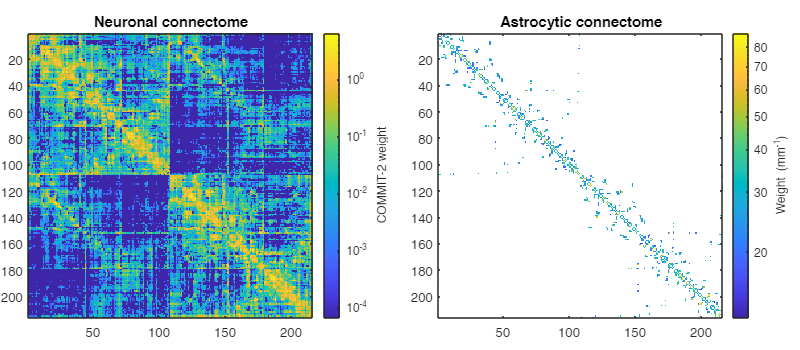

h_tile = nexttile(h_lay);
imagesc(h_tile, C_a, 'AlphaData', C_a > 0)
axis(h_tile, 'square')
h_tile.ColorScale = 'log';
cb = colorbar(h_tile);
cb.Label.String = 'Weight (mm^{-1})';
[cb.Limits(1), cb.Limits(2)] = bounds(C_a(C_a > 0));
clim(h_tile, cb.Limits)
title(h_tile, 'Astrocytic connectome')

## Representing the simulated data

After running '`nnamm_simulations.m`' and analyzing the resulting activities.

- Loads data

in_file = fullfile(proj_dir, 'data', 'simulations', 'parameters.mat');
P = load(in_file);

in_file = fullfile(proj_dir, 'data', 'simulations', 'grid.mat');
G = load(in_file);

in_file = fullfile(proj_dir, 'data', 'analyses', 'activity', 'papaya-r1', ...
    'activity.whole-brain.mean.xls');
T = readtable(in_file, 'VariableNamingRule', 'preserve');

- Sets up figure

h_fig = figure('Position', [0, 0, 800, 600]);
h_lay = tiledlayout(h_fig, 2, 2, 'Padding', 'tight', 'TileSpacing', 'compact');

- Exploration parameter space

h_tile = nexttile(h_lay);
scatter(h_tile, G.omega_GABA, G.omega_Glu, 8, 'filled')
% hold(h_tile, 'on')
% scatter(h_tile, P.baseline.omega_GABA, P.baseline.omega_Glu, 8, 'filled')
% hold(h_tile, 'off')

axis(h_tile, 'tight')
xlabel(h_tile, 'ω_{GABA} ({µmol}^{-1})')
ylabel(h_tile, 'ω_{Glu} ({µmol}^{-1})')
title(h_tile, 'Simulation parameter plane')

- Data from steady-state calculations

h_tile = nexttile(h_lay);
[X, Y, X_q_norm, Y_q_norm, X_q, Y_q] = setup_interp_coord(G.omega_GABA, ...
    G.omega_Glu, 1000, 1000);
F = scatteredInterpolant(X, Y, G.GABA_e, 'natural', 'none');
V_q = F(X_q_norm, Y_q_norm);
mask = ~isnan(V_q);
imagesc(h_tile, X_q(1, [1, end]), Y_q([1, end], 1), V_q, 'AlphaData', mask)

axis(h_tile, 'tight')
h_tile.YDir = 'normal';
cb = colorbar(h_tile);
cb.Label.String = 'GABA_e (µmol)';
[cb.Limits(1), cb.Limits(2)] = bounds(V_q(~isnan(V_q)));
xlabel(h_tile, 'ω_{GABA} ({µmol}^{-1})')
ylabel(h_tile, 'ω_{Glu} ({µmol}^{-1})')
title(h_tile, 'Theoretical astrocytic modulation')

- Different representation of the exploration parameter space

h_tile = nexttile(h_lay);
hold(h_tile, 'on')
scatter(h_tile, G.v_GABA, G.v_Glu, 8, 'filled')
scatter(h_tile, P.baseline.v_GABA, P.baseline.v_Glu, 8, 'filled')
hold(h_tile, 'off')

axis(h_tile, 'tight')
legend(h_tile, {'target state', 'initial state'}, 'Location', 'best')
xlabel(h_tile, 'v_{GABA} (mV)')
ylabel(h_tile, 'v_{Glu} (mV)')
title(h_tile, 'Simulation parameter grid')

- Data from stochastic network simulations

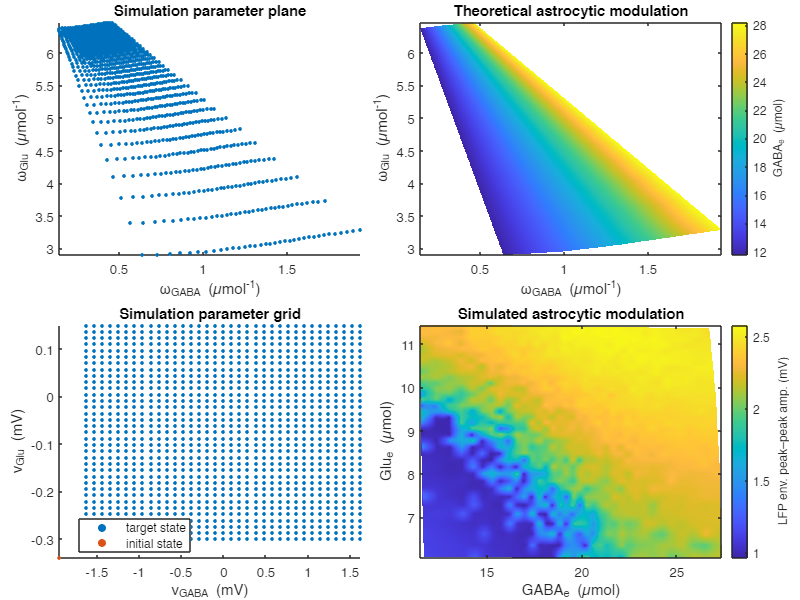

h_tile = nexttile(h_lay);
[X, Y, X_q_norm, Y_q_norm, X_q, Y_q] = setup_interp_coord(T.GABA_e, T.Glu_e, ...
    1000, 1000);
F = scatteredInterpolant(X, Y, T.('LFP-env_peak-to-peak-amp'), 'natural', ...
    'none');
V_q = F(X_q_norm, Y_q_norm);
mask = ~isnan(V_q);
imagesc(h_tile, X_q(1, [1, end]), Y_q([1, end], 1), V_q, 'AlphaData', mask)

axis(h_tile, 'tight')
h_tile.YDir = 'normal';
cb = colorbar(h_tile);
cb.Label.String = 'LFP env. peak–peak amp. (mV)';
[cb.Limits(1), cb.Limits(2)] = bounds(V_q(~isnan(V_q)));
xlabel(h_tile, 'GABA_e (µmol)')
ylabel(h_tile, 'Glu_e (µmol)')
title(h_tile, 'Simulated astrocytic modulation')

## Representing the bifurcation data

After running '`bd_draw_alpha.m`', '`matcont_analysis.m`' and '`pydstool_analysis.py`'.

- Loads data

bd_dir = fullfile(proj_dir, 'data', 'bifurcation-diagrams', 'alpha');
bd_name = 'C_Pyr_to_Pyr-0';
bd_lgd = 'C^{Pyr\rightarrowPyr} = 0';

bd_file = fullfile(bd_dir, sprintf('%s.bd.mat', bd_name));
BD = load(bd_file);

in_file = fullfile(bd_dir, sprintf('%s.hopf.mat', bd_name));
H = load_from_mat(in_file, 'Results');

in_file = fullfile(bd_dir, sprintf('%s.saddle-node.mat', bd_name));
SN = load_from_mat(in_file, 'Results');

- Sets up data

var_z = {1, 'E_Pyr'}; % {ode_index, var_name};
v_Glu_lim = [-0.045, 0.045];
v_Glu_lcc = 0; % this can be a vector of values (within the v_Glu_lim interval)

curves = [];
curves.bd = namm_setup_bd(BD.P, struct('name', 'v_Glu', 'lim', v_Glu_lim), ...
    var_z{2});
curves.hopf = matcont_hopf('', '', false, var_z{1}, BD, H, SN);
curves.saddle_node = matcont_saddle_node('', '', var_z{1}, BD, SN);
curves.points = matcont_special_points(H, SN, BD, var_z{1});
curves.lcc = pydstool_setup_lcc(bd_file, BD, v_Glu_lcc, struct( ...
    'var', var_z{2}, 'par', 'v_Glu', 'ver', 'lcc'));

- Sets up display

c_map_d = lines(5);
fig_opt.colors = struct('sn', c_map_d(5, :), 'ns', c_map_d(4, :), ...
    'uh', c_map_d(2, :), 'sh', c_map_d(1, :), 'p', c_map_d(3, :), 'lc', [0, 0, 0]);
fig_opt.legends = struct('x', 'q (Hz)', 'y', 'v_{Glu} (mV)', ...
    'z', 'E_{Pyr} (mV)', 'c', 'Frequency (Hz)', ...
    'c_2d', {{'H^s', 'sh'; 'H^u', 'uh'; 'SN', 'sn'; 'NS', 'ns'}}, ...
    'c_3d', {{'E', 'p'; 'H^s', 'sh'; 'H^u', 'uh'; 'SN', 'sn'; 'LC', 'lc'}});
fig_opt.marker_size_2d = 80;
fig_opt.markers = {
    'GH', '^';
    'BT', 'square';
    'CP', 'o';
    };

h_fig = figure('Position', [0, 0, 800, 800]);
h_lay = tiledlayout(h_fig, 2, 2, 'Padding', 'tight', 'TileSpacing', 'compact');
title(h_lay, ['Diagrams with ', bd_lgd])

- Codimension-2 diagram in 2D

h_tile = nexttile(h_lay);

% - Curves
hold(h_tile, 'on')
c = curves.saddle_node;
plot(h_tile, c.X, c.Y, 'Color', fig_opt.colors.sn)
c = curves.hopf;
mask = ~strcmp(c.S, 'N');
plot(h_tile, mask_where(c.X, mask, NaN), mask_where(c.Y, mask, NaN), ...
    'Color', fig_opt.colors.ns)
mask = ~strcmp(c.S, 'U');
plot(h_tile, mask_where(c.X, mask, NaN), mask_where(c.Y, mask, NaN), ...
    'Color', fig_opt.colors.uh)
mask = ~strcmp(c.S, 'S');
plot(h_tile, mask_where(c.X, mask, NaN), mask_where(c.Y, mask, NaN), ...
    'Color', fig_opt.colors.sh)
for k_p = 1 : size(curves.points, 1)
    P = curves.points(k_p, :);
    m = fig_opt.markers{strcmp(P.label, fig_opt.markers(:, 1)), 2};
    scatter(h_tile, P.X, P.Y, fig_opt.marker_size_2d, fig_opt.colors.p, ...
        'filled', m, 'MarkerEdgeColor', [0, 0, 0])
end
hold(h_tile, 'off')

% - Legends
hold(h_tile, 'on')
L = fig_opt.legends.c_2d(:, 2);
for k = 1 : numel(L)
    plot(h_tile, NaN, 'Color', fig_opt.colors.(L{k}))
end
L = fig_opt.markers(:, 2);
for k = 1 : numel(L)
    scatter(h_tile, NaN, NaN, fig_opt.marker_size_2d, fig_opt.colors.p, ...
        'filled', L{k}, 'MarkerEdgeColor', [0, 0, 0])
end
L = flipud(h_tile.Children(1 : (size(fig_opt.legends.c_2d, 1) + size( ...
    fig_opt.markers, 1))));
legend(h_tile, L, [fig_opt.legends.c_2d(:, 1); fig_opt.markers(:, 1)], ...
    'Location', 'best');
hold(h_tile, 'off')

% - Axis formatting
axis(h_tile, 'tight')
ylim(h_tile, [-6, 6])
xlabel(h_tile, fig_opt.legends.x)
ylabel(h_tile, fig_opt.legends.y)

- Amplitude extrema of limit cycles in 3D

h_tile = nexttile(h_lay);

% - Curves
hold(h_tile, 'on')
c = curves.saddle_node;
plot3(h_tile, c.X, c.Y, c.Z, 'Color', fig_opt.colors.sn)
c = curves.hopf;
mask = ~strcmp(c.S, 'U');
plot3(h_tile, mask_where(c.X, mask, NaN), mask_where(c.Y, mask, NaN), ...
    mask_where(c.Z, mask, NaN), 'Color', fig_opt.colors.uh)
mask = ~strcmp(c.S, 'S');
plot3(h_tile, mask_where(c.X, mask, NaN), mask_where(c.Y, mask, NaN), ...
    mask_where(c.Z, mask, NaN), 'Color', fig_opt.colors.sh)
c = curves.bd;
surf(h_tile, c.X, c.Y, c.Z, 'EdgeColor', 'none', ...
    'FaceAlpha', 0.8, 'FaceColor', fig_opt.colors.p, 'LineStyle', 'none')
for k_c = 1 : numel(curves.lcc)
    c = curves.lcc(k_c);
    plot3(h_tile, c.X, c.Y, c.Z(:, 1), 'Color', [0, 0, 0], 'Marker', 'none')
    plot3(h_tile, c.X, c.Y, c.Z(:, 2), 'Color', [0, 0, 0], 'Marker', 'none')
end
hold(h_tile, 'off')

% - Legends
hold(h_tile, 'on')
L = fig_opt.legends.c_3d(:, 2);
n = numel(L);
for k = 1 : n
    plot(h_tile, NaN, 'Color', fig_opt.colors.(L{k}))
end
L = flipud(h_tile.Children(1 : n));
legend(h_tile, L, fig_opt.legends.c_3d(:, 1), 'Location', 'best');
hold(h_tile, 'off')

% - Axis formatting
axis(h_tile, 'tight')
view(h_tile, [-45, 30])
ylim(h_tile, v_Glu_lim)
xlabel(h_tile, fig_opt.legends.x)
ylabel(h_tile, fig_opt.legends.y)
zlabel(h_tile, fig_opt.legends.z)

- Jansen–Rit diagram

h_tile = nexttile(h_lay);

% - Curves
hold(h_tile, 'on')
mask = find(cellfun(@(c) c.param.v_Glu, BD.P, 'UniformOutput', true) == 0, 1);
xy = [BD.P{mask}.q, BD.P{mask}.E_Pyr];
plot(h_tile, xy(:, 1), xy(:, 2), 'Color', [0, 0, 0], 'LineWidth', 2)
for k_b = 1 : size(BD.P{mask}.bif_label.k_sing, 1)
    k_sing = BD.P{mask}.bif_label.k_sing{k_b, 2};
    switch BD.P{mask}.bif_label.k_sing{k_b, 1}
        case 'saddle'
            scatter(h_tile, xy(k_sing, 1), xy(k_sing, 2), fig_opt.marker_size_2d, ...
                [0, 0, 0], 'filled', '^')
        case 'hopf'
            scatter(h_tile, xy(k_sing, 1), xy(k_sing, 2), fig_opt.marker_size_2d, ...
                [0, 0, 0], 'filled', 'o')
    end
end
for k_c = 1 : numel(curves.lcc)
    c = curves.lcc(k_c);
    patch(h_tile, [c.X; NaN], [c.Z(:, 1); NaN], [1 ./ c.T; NaN], ...
        'EdgeColor', 'interp', 'LineWidth', 3, 'Marker', 'none')
    patch(h_tile, [c.X; NaN], [c.Z(:, 2); NaN], [1 ./ c.T; NaN], ...
        'EdgeColor', 'interp', 'LineWidth', 3, 'Marker', 'none')
end
hold(h_tile, 'off')

% - Legends
hold(h_tile, 'on')
plot(h_tile, NaN, NaN, 'Color', [0, 0, 0], 'LineWidth', 2)
scatter(h_tile, NaN, NaN, fig_opt.marker_size_2d, [0, 0, 0], 'filled', '^')
scatter(h_tile, NaN, NaN, fig_opt.marker_size_2d, [0, 0, 0], 'filled', 'o')
L = flipud(h_tile.Children(1 : 3));
legend(h_tile, L, {'E', 'SN', 'H'}, 'Location', 'best');
hold(h_tile, 'off')

% - Axis formatting
axis(h_tile, 'tight')
cb = colorbar(h_tile, 'Location', 'northoutside');
cb.Label.String = fig_opt.legends.c;
xlabel(h_tile, fig_opt.legends.x)
ylabel(h_tile, fig_opt.legends.z)

- Limit cycle frequencies in 3D

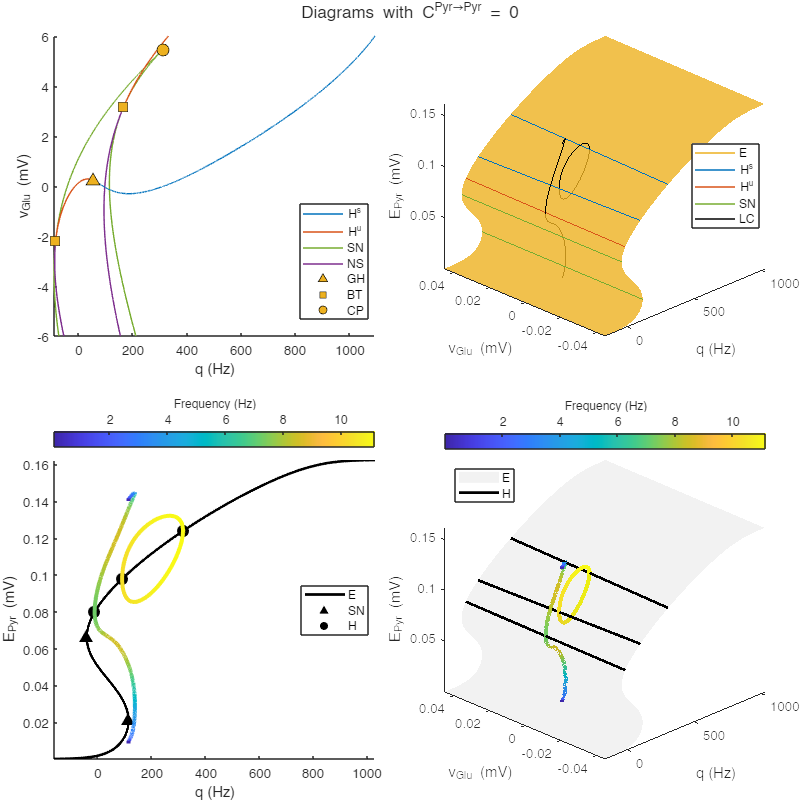

h_tile = nexttile(h_lay);

% - Curves
hold(h_tile, 'on')
c = curves.bd;
surf(h_tile, c.X, c.Y, c.Z, 'EdgeColor', 'none', 'FaceColor', [0, 0, 0], ...
    'FaceAlpha', 0.05, 'LineStyle', 'none')
c = curves.hopf;
mask = strcmp(c.S, 'N');
plot3(h_tile, mask_where(c.X, mask, NaN), mask_where(c.Y, mask, NaN), ...
    mask_where(c.Z, mask, NaN), 'Color', [0, 0, 0], 'LineWidth', 2, ...
    'Marker', 'none')
for k_c = 1 : numel(curves.lcc)
    c = curves.lcc(k_c);
    patch(h_tile, [c.X; NaN], [c.Y; NaN], [c.Z(:, 1); NaN], [1 ./ c.T; NaN], ...
        'EdgeColor', 'interp', 'LineWidth', 3, 'Marker', 'none')
    patch(h_tile, [c.X; NaN], [c.Y; NaN], [c.Z(:, 2); NaN], [1 ./ c.T; NaN], ...
        'EdgeColor', 'interp', 'LineWidth', 3, 'Marker', 'none')
end
hold(h_tile, 'off')

% - Legends
hold(h_tile, 'on')
surf(h_tile, NaN(2), NaN(2), NaN(2), 'EdgeColor', 'none', ...
    'FaceAlpha', 0.05, 'FaceColor', [0, 0, 0], 'LineStyle', 'none')
plot(h_tile, NaN, NaN, 'Color', [0, 0, 0], 'LineWidth', 2)
legend(h_tile, h_tile.Children([2, 1]), {'E', 'H'}, 'Location', 'best');
hold(h_tile, 'off')

% - Axis formatting
axis(h_tile, 'tight')
view(h_tile, [-45, 30])
ylim(h_tile, v_Glu_lim)
cb = colorbar(h_tile, 'Location', 'northoutside');
cb.Label.String = fig_opt.legends.c;
xlabel(h_tile, fig_opt.legends.x)
ylabel(h_tile, fig_opt.legends.y)
zlabel(h_tile, fig_opt.legends.z)

## Representing more complex data

- Loads and sets up data

in_file = fullfile(proj_dir, 'data', 'simulations', 'parameters.mat');
P = load(in_file);

in_file = fullfile(proj_dir, 'data', 'simulations', 'grid.mat');
G = load(in_file);

in_file = fullfile(proj_dir, 'data', 'analyses', 'activity', 'papaya-r1', ...
    'activity.whole-brain.mean.xls');
T = readtable(in_file, 'VariableNamingRule', 'preserve');

bd_dir = fullfile(proj_dir, 'data', 'bifurcation-diagrams', 'alpha');
bd_name = 'C_Pyr_to_Pyr-7.5';

in_file = fullfile(bd_dir, sprintf('%s.bd.mat', bd_name));
BD = load_from_mat(in_file, 'default_param');

in_file = fullfile(bd_dir, sprintf('%s.lcc.mat', bd_name));
LCC = load(in_file);

par_x = {'q', 'q (Hz)'}; % {par_name, legend};
par_y = {'v_Glu', 'v_{Glu} (mV)'}; % {par_name, legend};
var_z = {1, 'E_Pyr', 'E_{Pyr} (mV)'}; % {ode_index, var_name, legend};

% * The goal here is to estimate contour lines of limit cycle peak–peak
%   amplitudes given a set of points through which isolines must pass through.
% * The points (representing contour line levels) are expressed in a particular
%   system of coordinates and so mapping functions are useful.
% * Original coordinates when drawing diagrams are (x = q; y = v_Glu). Here we
%   want to specify (GABA_e, Glu_e) coordinates. Thus, we must define:
%   f_x(x) = GABA_e, f_y(y) = Glu_e, f_x_inv(GABA_e) = x, f_y_inv(Glu_e) = y.
% * Remember, from the equation of singular points, that v_GABA and q linearly
%   combine, through the constant a / A.
lcca_opt = struct('var', var_z{2}, 'x_par', par_x{1}, 'y_par', par_y{1}, ...
    'f_x', @(v) sigmoid_inv((P.q.mean + BD.v_GABA * BD.a / BD.A - v) * (P.A / ...
    P.a), P.m_GABA_Pyr, P.r_GABA_Pyr, P.theta_GABA_Pyr, P.delta_GABA_Pyr), ...
    'f_x_inv', @(v) P.q.mean + BD.v_GABA * BD.a / BD.A - (P.a / P.A) * sigmoid( ...
    v, P.m_GABA_Pyr, P.r_GABA_Pyr, P.theta_GABA_Pyr, P.delta_GABA_Pyr), ...
    'f_y', @(v) sigmoid_inv(v, P.m_Glu_Pyr, P.r_Glu_Pyr, P.theta_Glu_Pyr, ...
    P.delta_Glu_Pyr), ...
    'f_y_inv', @(v) sigmoid(v, P.m_Glu_Pyr, P.r_Glu_Pyr, P.theta_Glu_Pyr, ...
    P.delta_Glu_Pyr), ...
    'levels', [16, 8; 16, 8.8; 16, 10;]);
lcca = namm_setup_lcca_isolines('', '', lcca_opt, LCC);

% * By default, Hopf continuations were done with (q, v_Glu), like LCC.
H = matcont_hopf(bd_dir, bd_name, false, var_z{1});

- Sets up display

h_fig = figure('Position', [0, 0, 800, 300]);
h_lay = tiledlayout(h_fig, 1, 2, 'Padding', 'tight', 'TileSpacing', 'compact');

- Overlay limit cycle peak–peak amplitude isolines

h_tile = nexttile(h_lay);

% - Simulation data
hold(h_tile, 'on')
[X, Y, X_q_norm, Y_q_norm, X_q, Y_q] = setup_interp_coord(T.GABA_e, T.Glu_e, ...
    1000, 1000);
F = scatteredInterpolant(X, Y, T.('LFP-env_peak-to-peak-amp'), 'natural', ...
    'none');
V_q = F(X_q_norm, Y_q_norm);
mask = ~isnan(V_q);
imagesc(h_tile, X_q(1, [1, end]), Y_q([1, end], 1), V_q, 'AlphaData', mask)
hold(h_tile, 'off')

% - Bifurcation data
hold(h_tile, 'on')
x_lim = min_max(X_q(:));
y_lim = min_max(Y_q(:));
x = lcca_opt.f_x(lcca.curves(:, 1));
y = lcca_opt.f_y(lcca.curves(:, 2));
mask = ~(is_in(x_lim, '<=', x, '<=') & is_in(y_lim, '<=', y, '<='));
x(mask, :) = NaN;
y(mask, :) = NaN;
plot(h_tile, x, y, 'Color', [0, 0, 0])
hold(h_tile, 'off')

% - Axis formatting
axis(h_tile, 'tight')
h_tile.YDir = 'normal';
cb = colorbar(h_tile);
cb.Label.String = 'LFP env. peak–peak amp. (mV)';
cb.Limits = min_max(V_q(~isnan(V_q)));
xlabel(h_tile, 'GABA_e (µmol)')
ylabel(h_tile, 'Glu_e (µmol)')
title(h_tile, 'Simulated astrocytic modulation')

- Bifurcation landscape of limit cycles

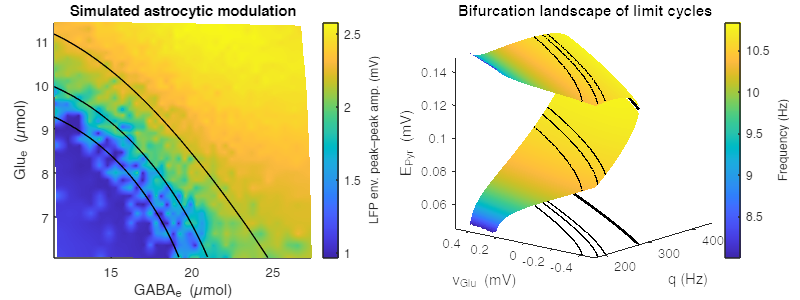

h_tile = nexttile(h_lay);

xy_lim = @(X, Y) (is_in([180, Inf], '<=', X, '<=') & is_in([-0.5, 0.5], ...
    '<=', Y, '<='));
c_mask = @(freq) (freq > 8);

% - LCC surface
hold(h_tile, 'on')
x = [LCC.(var_z{2}).(par_x{1}), LCC.(var_z{2}).(par_x{1})];
y = [LCC.(var_z{2}).(par_y{1}), LCC.(var_z{2}).(par_y{1})];
z = [LCC.(var_z{2}).max, LCC.(var_z{2}).min];
c = [LCC.(var_z{2}).freq, LCC.(var_z{2}).freq];
mask = (c_mask(c) & xy_lim(x, y));
x_lim = min_max(x(mask));
y_lim = min_max(y(mask));
z_lim = min_max(z(mask));
c_lim = min_max(c(mask));
surf(h_tile, x, y, z, c, 'AlphaData', mask, 'EdgeColor', 'none', ...
    'FaceAlpha', 'flat', 'FaceColor', 'flat')
hold(h_tile, 'off')

% - LCC contour lines
hold(h_tile, 'on')
x = lcca.curves(:, 1);
y = lcca.curves(:, 2);
z = lcca.curves(:, 3 : end);
mask = ~xy_lim(x, y);
x(mask) = NaN;
y(mask) = NaN;
z(mask, :) = NaN;
plot3(h_tile, x, y, [z, z_lim(1) * ones(size(mask))], 'Color', [0, 0, 0], ...
    'LineWidth', 1)
hold(h_tile, 'off')

% - Hopf curve
hold(h_tile, 'on')
x = H.X;
y = H.Y;
z = H.Z;
mask = ~xy_lim(x, y);
x(mask) = NaN;
y(mask) = NaN;
z(mask) = NaN;
plot3(h_tile, x, y, [z, z_lim(1) * ones(size(mask))], 'Color', [0, 0, 0], ...
    'LineWidth', 2)
hold(h_tile, 'off')

% - Axis formatting
axis(h_tile, 'tight')
clim(h_tile, c_lim)
view(h_tile, [-50, 15])
xlim(h_tile, x_lim)
ylim(h_tile, y_lim)
zlim(h_tile, z_lim)
cb = colorbar(h_tile);
cb.Label.String = 'Frequency (Hz)';
xlabel(h_tile, par_x{2})
ylabel(h_tile, par_y{2})
zlabel(h_tile, var_z{3})
title(h_tile, 'Bifurcation landscape of limit cycles')